# MST不変量のテンソルネットワークによる計算

## 概要

Sweedler algebraをHopf algebraの具体例としてMST不変量を局所的に計算する．

テンソルネットワークの表示を持ちいて，テンソル計算を行う．

`makeTensorExpression関数を用いて，テンソルネットワークの具体的な計算を行うMATLAB式を返す関数を作成した．`

`結果として，ひものRI moveによる補空間の変化をテンソルネットワークで検出する問題への回答を与える．`

## `代数,定数の定義`

`SweederAlgがSweedler algebraの定義クラスである．`

`生成元を取得して，verifyHopf関数でHopf algebraの関係式をすべてチェックする．`

`エラーを出してないので，問題なく構造定数が設定されている．`

[Z,K_,E_]=SweedlerAlg.getGenerator;
Z.verifyHopf(@isequal)

構造定数をすべて取得する．ワークスペース変数を設定しておく必要がある．

Un=eye(Z.dim);
An=Z.getSC('_S');
Mu=Z.getSC('_μ');
De=Z.getSC('_Δ');
Et=Z.getSC('_η');
Ep=Z.getSC('_ε');
Ir=Z.getSC('_intr');
Il=Z.getSC('_intl');
Cr=Z.getSC('_cointr');
Cl=Z.getSC('_cointl');
Tp=TP(De,Mu,2,2);
Tm=TP(TP(De,An,2,1),Mu,3,2);

## テンソル計算

MATLABのtensorprod関数を用いたテンソルの計算を紹介する．

たとえば，o-graphのtwistingに関する補題の具体的な検証は下記のようなテンソル計算で行われる．

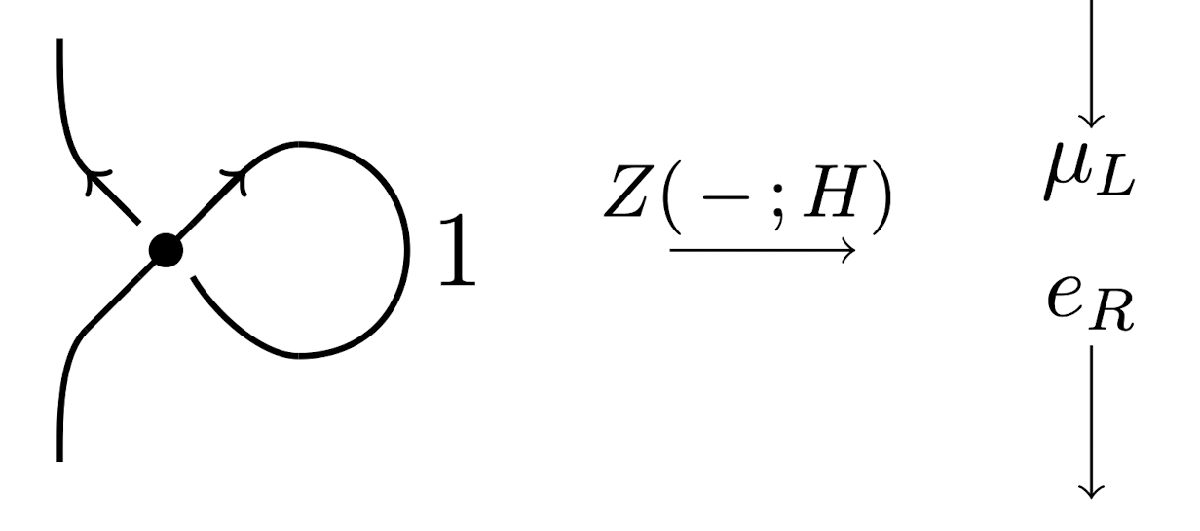

TP(TP(Mu,An^2,3,1),De,[3 2],[1 2])

ans =      0     0     0     0
     0     0     0     0
     0     0    -1    -1
     0     0     0     0


TP(Il,Cr,N=1)

ans =      0     0     0     0
     0     0     0     0
     0     0    -1    -1
     0     0     0     0


同じ2階テンソル(行列)が対応している．

## makeTensorExpression関数

上記の計算をより行いやすくする関数がmakeTensorExpression関数である．

上記の補題をより見やすい表記にして，図式のテンソルネットワークから，

MATLABの計算式exprを取得する事ができる．

expr=makeTensorExpression('Mu{1,2,3}Cl{3}(An^-2){1,2}',[])

expr = 'permute(tensorprod(tensorprod(1*Mu,Cl,3,1),(An^-2),[1 2],[1 2]),zeros(1,0))'

expr=makeTensorExpression('Mu{1,2,3}(An^2){3,4}De{4,2,5}',[1 5])

expr = 'permute(tensorprod(tensorprod(1*Mu,(An^2),3,1),De,[3 2],[1 2]),[1 2])'

eval(expr)

ans =      0     0     0     0
     0     0     0     0
     0     0    -1    -1
     0     0     0     0


expr=makeTensorExpression('Il{1}Cr{2}',[1 2])

expr = 'permute(tensorprod(1*Il,Cr,[],[],N=1),[1 2])'

eval(expr)

ans =      0     0     0     0
     0     0     0     0
     0     0    -1    -1
     0     0     0     0


## 実例の計算

下記のテンソルネットワークの計算を行う．

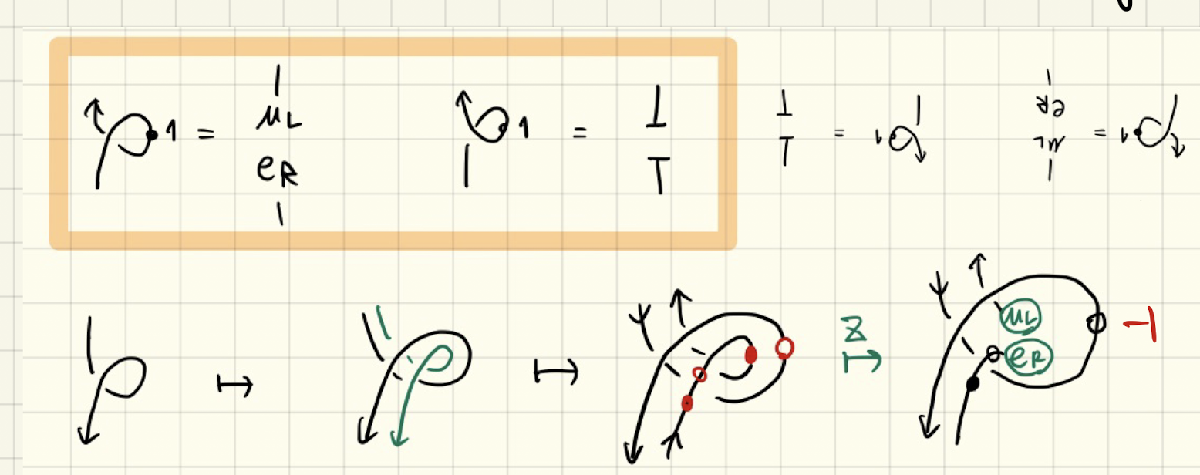

四面体の各交点に4階テンソルを対応させて，テンソルネットワークの計算を行う．

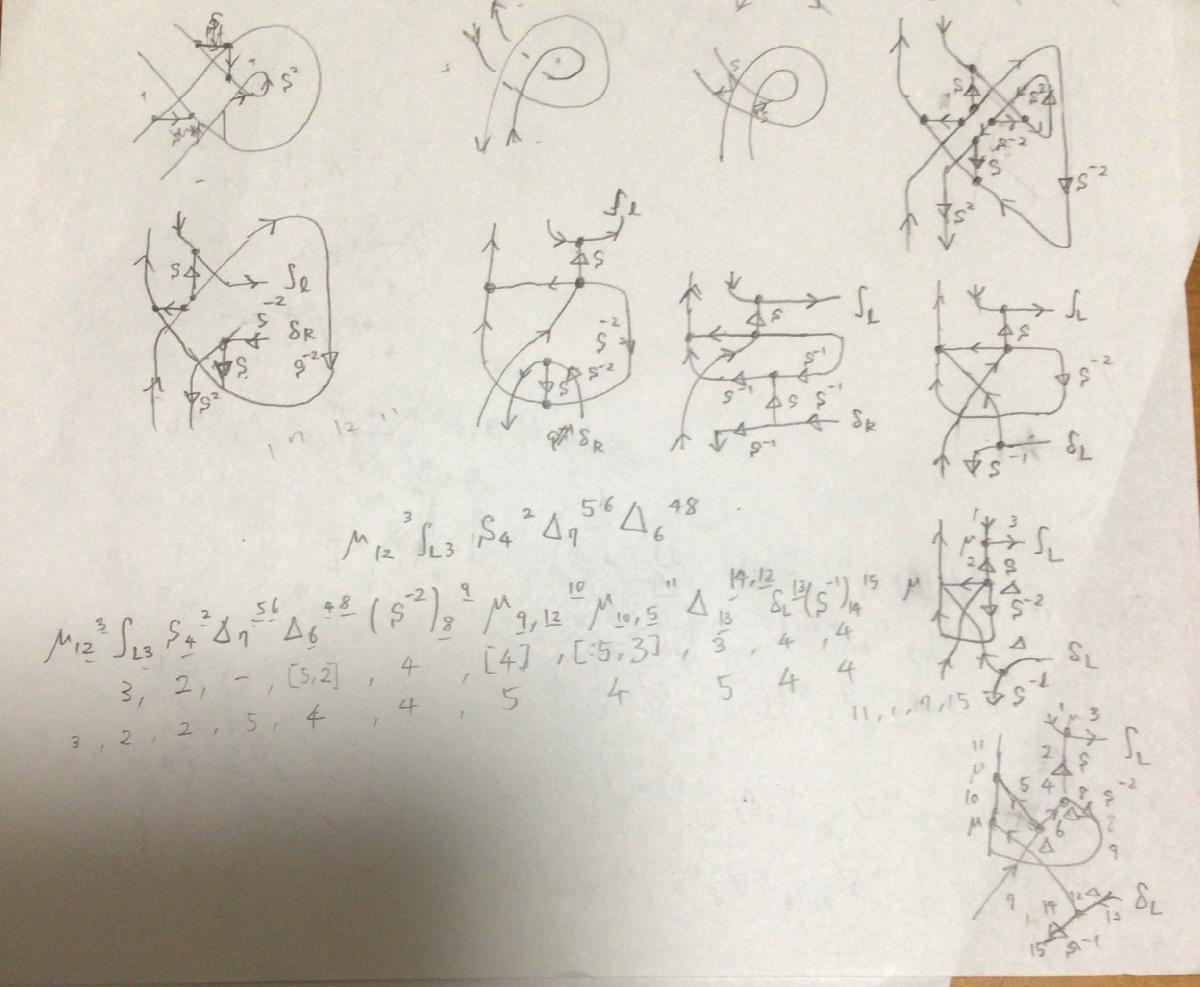

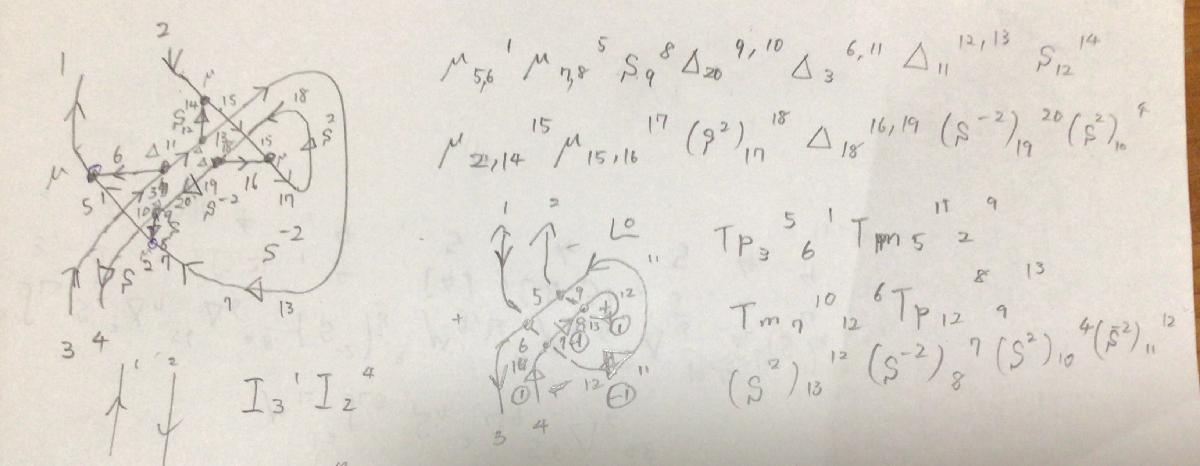

3通りの計算を行った結果，同じテンソルexpr1,expr2,expr3が得られた．四面体を直接テンソルに書き換えるのが最も効率的な計算方法である．

[expr,acc]=makeTensorExpression( ...
    'Mu{1,2,3}Il{3}An{4,2}De{7,5,6}De{6,4,8}(An^-2){8,9}Mu{9,12,10}Mu{10,5,11}De{13,14,12}Cl{13}(An^-1){14,15}' ...
    ,[11 1 7 15])

expr = 'permute(tensorprod(tensorprod(tensorprod(tensorprod(tensorprod(tensorprod(tensorprod(tensorprod(tensorprod(tensorprod(1*Mu,Il,3,1),An,2,2),De,[],[]),De,[5 2],[1 2]),(An^-2),4,1),Mu,4,1),Mu,[5 3],[1 2]),De,3,3),Cl,4,1),(An^-1),4,1),[3 1 2 4])'

acc =      1     7    11    15


expr1=reshape(eval(expr),16,16);
makeTensorExpression(['Mu{5,6,1}Mu{7,8,5}An{9,8}De{20,9,10}De{3,6,11}De{11,12,13}An{12,14}' ...
    'Mu{2,14,15}Mu{15,16,17}(An^2){17,18}De{18,16,19}(An^-2){19,20}(An^2){10,4}(An^2){13,7}'],1:4)

ans = 'permute(tensorprod(tensorprod(tensorprod(tensorprod(tensorprod(tensorprod(tensorprod(tensorprod(tensorprod(tensorprod(tensorprod(tensorprod(tensorprod(1*Mu,Mu,1,3),An,4,2),De,4,2),De,1,2),De,6,1),An,6,1),Mu,7,2),Mu,8,1),(An^2),9,1),De,[9 8],[1 2]),(An^-2),[8 3],[1 2]),(An^2),3,1),(An^2),[4 2],[1 2]),[1 3 2 4])'

expr2=reshape(eval(expr),16,16);
isequal(expr1,expr2)

ans = logical
   1

disp(expr1)

     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1
     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0
     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0
     0     0     0    -1     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0
     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0
     0     0     0     0     0     0    -1     0     0     0     0     0     0     0     0     0
     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0    -1     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0    -1     0     0     0
     1     0     0     0     0

disp(sum(abs(expr1)))

     1     1     1     1     1     1     1     1     1     1     3     3     1     1     3     3


makeTensorExpression(['Tp{5,3,6,1}Tm{5,11,2,9}Tm{7,10,12,6}Tp{12,8,9,13}(An^2){13,12}(An^-2){8,7}(An^2){10,4}(An^-2){11,12}'],1:4)

ans = 'permute(tensorprod(tensorprod(tensorprod(tensorprod(tensorprod(tensorprod(tensorprod(1*Tp,Tm,1,1),Tm,2,4),Tp,[8 5],[1 3]),(An^2),8,1),(An^-2),[7 5],[1 2]),(An^2),5,1),(An^-2),[3 5],[1 2]),[2 3 1 4])'

expr3=reshape(eval(expr),16,16)

expr3 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1
     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0
     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0
     0     0     0    -1     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0
     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0
     0     0     0     0     0     0    -1     0     0     0     0     0     0     0     0     0
     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0    -1     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0    -1     0     0     0


isequal(expr1,expr3)

ans = logical
   1

## 問1に関する考察

Sweedlerではframingの変化をキャッチ出来なかった．$S^4 =\mathrm{id}$であることが原因と思われる．

expr=makeTensorExpression(['Tp{5,3,6,1}Tm{5,13,2,11}Tm{8,4,12,7}Tp{16,9,10,15}' ...
    '(An^4){7,6}(An^-2){9,8}(An^-4){11,10}(An^2){1,3}(An^-2){14,2}(An^2){15,16}(An^-2){13,12}(An^2){4,14}'])

expr = 'permute(tensorprod(tensorprod(tensorprod(tensorprod(tensorprod(tensorprod(tensorprod(tensorprod(tensorprod(tensorprod(tensorprod(1*Tp,Tm,1,1),Tm,[],[]),Tp,[],[]),(An^4),[10 2],[1 2]),(An^-2),[10 6],[1 2]),(An^-4),[5 9],[1 2]),(An^2),[2 1],[1 2]),(An^-2),2,2),(An^2),[5 4],[1 2]),(An^-2),[1 3],[1 2]),(An^2),[1 2],[1 2]),[1 2])'

eval(expr)

ans = 2

expr=makeTensorExpression(['Tp{5,3,6,1}Tm{5,13,2,11}Tm{8,4,12,7}Tp{16,9,10,15}' ...
    '(Un){7,6}(An^-2){9,8}(Un){11,10}(An^2){1,3}(An^-2){14,2}(An^2){15,16}(An^-2){13,12}(An^2){4,14}'])

expr = 'permute(tensorprod(tensorprod(tensorprod(tensorprod(tensorprod(tensorprod(tensorprod(tensorprod(tensorprod(tensorprod(tensorprod(1*Tp,Tm,1,1),Tm,[],[]),Tp,[],[]),(Un),[10 2],[1 2]),(An^-2),[10 6],[1 2]),(Un),[5 9],[1 2]),(An^2),[2 1],[1 2]),(An^-2),2,2),(An^2),[5 4],[1 2]),(An^-2),[1 3],[1 2]),(An^2),[1 2],[1 2]),[1 2])'

eval(expr)

ans = 2

expr=makeTensorExpression(['Tp{5,3,6,1}Tm{5,13,2,11}Tm{8,4,12,7}Tp{16,9,10,15}' ...
    '(Un){7,6}(An^-2){9,8}(Un){11,10}(An^2){1,3}(Un){4,2}(An^2){15,16}(An^-2){13,12}'])

expr = 'permute(tensorprod(tensorprod(tensorprod(tensorprod(tensorprod(tensorprod(tensorprod(tensorprod(tensorprod(tensorprod(1*Tp,Tm,1,1),Tm,[],[]),Tp,[],[]),(Un),[10 2],[1 2]),(An^-2),[10 6],[1 2]),(Un),[5 9],[1 2]),(An^2),[2 1],[1 2]),(Un),[3 2],[1 2]),(An^2),[4 3],[1 2]),(An^-2),[1 2],[1 2]),[1 2])'

eval(expr)

ans = 2

他のホップ代数